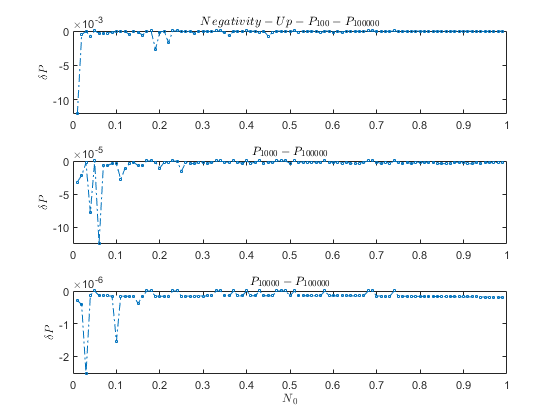


% FigureBoundComparehh(GDedata1PSOA(3:end,:) ,GDedata1A(3:end,:)  ,GDedata1PSOB(3:end,:)  ,GDedata1B (3:end,:) ,GDedata1PSOC(3:end,:)  ,GDedata1C(3:end,:)  ,"Negativity","Up")
% FigureBoundComparehh(GDedata2PSOA,GDedata2A,GDedata2PSOB,GDedata2B,GDedata2PSOC,GDedata2C,"Negativity","Low")
% FigureBoundComparehh(GDedata11PSOA,GDedata11A,GDedata11PSOB,GDedata11B,GDedata11PSOC,GDedata11C,"Concurrence","Up")
% FigureBoundComparehh(GDedata22PSOA,GDedata22A,GDedata22PSOB,GDedata22B,GDedata22PSOC,GDedata22C,"Concurrence","Low")

FigureBoundComparehh2(GDedata1C,GDedata1B,GDedata1A,GDedata1,"Negativity","Up")

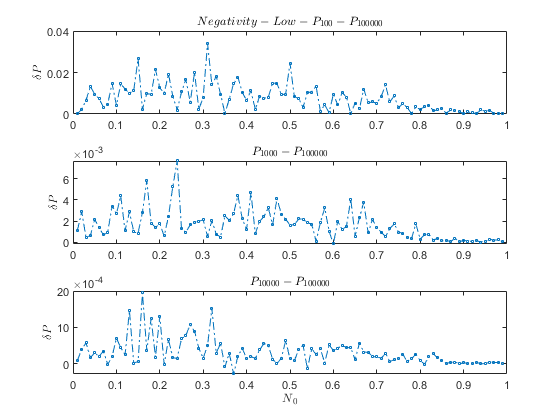

FigureBoundComparehh2(GDedata2C,GDedata2B,GDedata2A,GDedata2,"Negativity","Low")

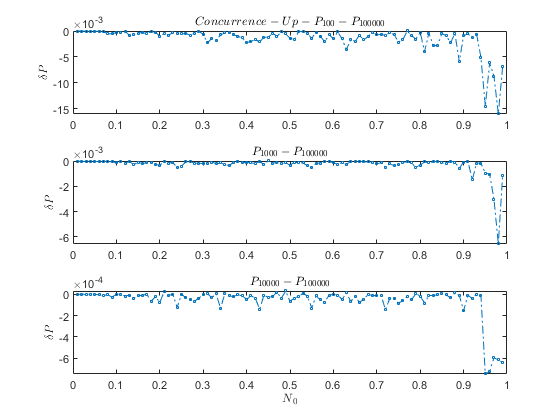

FigureBoundComparehh2(GDedata11C,GDedata11B,GDedata11A,GDedata11,"Concurrence","Up")

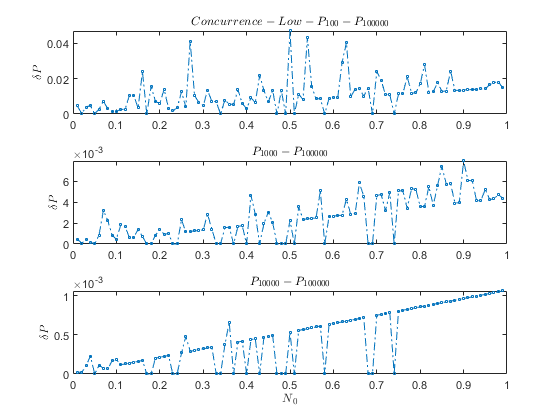

FigureBoundComparehh2(GDedata22C,GDedata22B,GDedata22A,GDedata22,"Concurrence","Low")

function FigureBoundComparehh(GDedata1PSOA,GDedata1A,GDedata1PSOB,GDedata1B,GDedata1PSOC,GDedata1C,measurement,Case)
figure
plot(GDedata1PSOA(:,1),GDedata1PSOA(:,5)-GDedata1A(:,5),'s-.',"MarkerSize",2)
hold on
plot(GDedata1PSOB(:,1),GDedata1PSOB(:,5)-GDedata1B(:,5),'s-.',"MarkerSize",2)
plot(GDedata1PSOC(:,1),GDedata1PSOC(:,5)-GDedata1C(:,5),'s-.',"MarkerSize",2)
ylabel("$\Delta P$","Interpreter","latex","FontSize",15)
xlabel("$ N_0$","Interpreter","latex","FontSize",15)
legend("$3000-50*60$","$4000-50*80$","$5000-50*100$","Interpreter","latex","FontSize",15,"Location","best")
legend('boxoff')
title(strcat("$","|\Gamma\rangle-",measurement,"-",Case,"Bound(P_{PSO}-P_{RS})","$"),"Interpreter","latex","FontSize",15)
end


function FigureBoundComparehh2(GDedata1,GDedata2,GDedata3,GDedata4,measurement,Case)
figure
tiledlayout(3,1)
ax1=nexttile;
plot(ax1,GDedata1(:,1),(GDedata1(:,5)-GDedata4(:,5)),'s-.',"MarkerSize",2)
ylabel(ax1,"$\delta P$","Interpreter","latex","FontSize",20)
title(ax1,strcat("$",measurement,"-",Case,"-","P_{100}-P_{100000}","$"),"Interpreter","latex","FontSize",20)
ax2=nexttile;
plot(ax2,GDedata2(:,1),(GDedata2(:,5)-GDedata4(:,5)) ,'s-.',"MarkerSize",2)
ylabel(ax2,"$\delta P$","Interpreter","latex","FontSize",20)
title(ax2,strcat("$","P_{1000}-P_{100000}","$"),"Interpreter","latex","FontSize",20)
ax3=nexttile;
plot(ax3,GDedata3(:,1),(GDedata3(:,5)-GDedata4(:,5))  ,'s-.',"MarkerSize",2)
ylabel(ax3,"$\delta P$","Interpreter","latex","FontSize",20)
title(ax3,strcat("$","P_{10000}-P_{100000}","$"),"Interpreter","latex","FontSize",20)
xlabel("$N_0$","Interpreter","latex","FontSize",15)
end